# RCI_2D

RCI model

## RCI model

### Useful matrix

clear;
Gamma_1_4 = sym(gamma_matric(1,4));
Gamma_1_5 = sym(gamma_matric(1,5));
Gamma_2_4 = sym(gamma_matric(2,4));
Gamma_2_5 = sym(gamma_matric(2,5));
%% useful tool



### k·p model

syms M u real;
syms k_x k_y k_z real;
assume(k_x <= pi & k_x >= -pi);
assume(k_y <= pi & k_y >= -pi);
assume(k_z <= pi & k_z >= -pi);
U = expm(-1i*pi*sym(gamma_matric(2,5))/4);
%
% M       = M0-M2*(k_x^2+k_y^2)-M1*(k_z^2);
% E0k     = C0+C2*(k_x^2+k_y^2)+C1*(k_z^2);
% k_plus  = k_x + 1i* k_y;
% k_minus = k_x - 1i* k_y;
%

RCI = Htrig(4)

RCI =   Htrig - 属性:

          Kinds: 1
          HcoeL: [4×4 sym]
          HnumL: [4×4 double]
     HsymL_trig: 1
      Htrig_sym: [4×4 sym]
      Basis_num: 4
             Rm: [3×3 double]
             Gk: [3×3 double]
    symvar_list: [1×0 sym]

\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)

%
RCI = RCI ...
    +Trig(sin(k_x) ,  gamma_matric(1) )...
    +Trig(sin(k_y) , gamma_matric(2))...
    +Trig(M-cos(k_x)-cos(k_y)   , gamma_matric(3) )...
    ;

Setting 1/1Htrig ...


Setting 1/1Htrig ...


Setting 3/3Htrig ...


RCI_sym = disp(RCI);

  Htrig - 属性:

          Kinds: 5
          HcoeL: [4×4×5 sym]
          HnumL: [4×4×5 double]
     HsymL_trig: [1    sin(k_x)    sin(k_y)    cos(k_x)    cos(k_y)]
      Htrig_sym: [4×4 sym]
      Basis_num: 4
             Rm: [3×3 double]
             Gk: [3×3 double]
    symvar_list: M

\left(\begin{array}{cccc} M-\cos\left(k_{x}\right)-\cos\left(k_{y}\right) & \sin\left(k_{x}\right) & 0 & -\sin\left(k_{y}\right)\\ \sin\left(k_{x}\right) & \cos\left(k_{x}\right)-M+\cos\left(k_{y}\right) & \sin\left(k_{y}\right) & 0\\ 0 & \sin\left(k_{y}\right) & M-\cos\left(k_{x}\right)-\cos\left(k_{y}\right) & \sin\left(k_{x}\right)\\ -\sin\left(k_{y}\right) & 0 & \sin\left(k_{x}\right) & \cos\left(k_{x}\right)-M+\cos\left(k_{y}\right) \end{array}\right)


syms m_1 m_2 m_3 m_4;
syms m_0 theta_0 theta_x theta_y m_x m_y  real;
m_1 = m_y*sin(theta_y);
m_3 = m_x*sin(theta_x);
m_2 = m_y*cos(theta_y);
m_4 = m_x*cos(theta_x);
m_x = m_0*cos(theta_0);
m_y = m_0*sin(theta_0) ;
delta_H = Htrig(4,Trig(m_1,Gamma_1_4)+Trig(m_2,Gamma_2_4)+Trig(m_3,Gamma_1_5)+Trig(m_4,Gamma_2_5));

Setting 1/1Htrig ...
Setting 1/1Htrig ...
Setting 1/1Htrig ...
Setting 1/1Htrig ...


delta_H.Htrig_sym   

$$ans = \begin{array}{l} \left(\begin{array}{cccc} m_{x}\,\sin\left(\theta_{x}\right)-m_{y}\,\cos\left(\theta_{y}\right) & 0 & \sigma_{2} & 0\\ 0 & -m_{y}\,\cos\left(\theta_{y}\right)-m_{x}\,\sin\left(\theta_{x}\right) & 0 & \sigma_{1}\\ \sigma_{2} & 0 & m_{y}\,\cos\left(\theta_{y}\right)-m_{x}\,\sin\left(\theta_{x}\right) & 0\\ 0 & \sigma_{1} & 0 & m_{y}\,\cos\left(\theta_{y}\right)+m_{x}\,\sin\left(\theta_{x}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{x}\,\cos\left(\theta_{x}\right)-m_{y}\,\sin\left(\theta_{y}\right)\\ \sigma_{2}=m_{x}\,\cos\left(\theta_{x}\right)+m_{y}\,\sin\left(\theta_{y}\right) \end{array}$$

RCI_PT = RCI + delta_H;

Setting 1/1Htrig ...


RCI_PT = RCI_PT <= 'POSCAR';
RCI_PT = RCI_PT <'KPOINTS';

syms theta_x theta_y theta_0 m_0 real
RCIPT = RCI_PT.Htrig_sym

$$RCIPT = \begin{array}{l} \left(\begin{array}{cccc} M-\cos\left(k_{x}\right)-\cos\left(k_{y}\right)-m_{y}\,\cos\left(\theta_{y}\right)+m_{x}\,\sin\left(\theta_{x}\right) & \sin\left(k_{x}\right) & \sigma_{2} & -\sin\left(k_{y}\right)\\ \sin\left(k_{x}\right) & \cos\left(k_{x}\right)-M+\cos\left(k_{y}\right)-m_{y}\,\cos\left(\theta_{y}\right)-m_{x}\,\sin\left(\theta_{x}\right) & \sin\left(k_{y}\right) & \sigma_{1}\\ \sigma_{2} & \sin\left(k_{y}\right) & M-\cos\left(k_{x}\right)-\cos\left(k_{y}\right)+m_{y}\,\cos\left(\theta_{y}\right)-m_{x}\,\sin\left(\theta_{x}\right) & \sin\left(k_{x}\right)\\ -\sin\left(k_{y}\right) & \sigma_{1} & \sin\left(k_{x}\right) & \cos\left(k_{x}\right)-M+\cos\left(k_{y}\right)+m_{y}\,\cos\left(\theta_{y}\right)+m_{x}\,\sin\left(\theta_{x}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{x}\,\cos\left(\theta_{x}\right)-m_{y}\,\sin\left(\theta_{y}\right)\\ \sigma_{2}=m_{x}\,\cos\left(\theta_{x}\right)+m_{y}\,\sin\left(\theta_{y}\right) \end{array}$$

C =m_1*gamma_matric(4)+m_3*gamma_matric(5)

$$C = \left(\begin{array}{cccc} 0 & -m_{x}\,\sin\left(\theta_{x}\right)\,\mathrm{i} & 0 & -m_{y}\,\sin\left(\theta_{y}\right)\,\mathrm{i}\\ m_{x}\,\sin\left(\theta_{x}\right)\,\mathrm{i} & 0 & m_{y}\,\sin\left(\theta_{y}\right)\,\mathrm{i} & 0\\ 0 & -m_{y}\,\sin\left(\theta_{y}\right)\,\mathrm{i} & 0 & m_{x}\,\sin\left(\theta_{x}\right)\,\mathrm{i}\\ m_{y}\,\sin\left(\theta_{y}\right)\,\mathrm{i} & 0 & -m_{x}\,\sin\left(\theta_{x}\right)\,\mathrm{i} & 0 \end{array}\right)$$

m_x = m_0*cos(theta_0);
m_y = m_0*sin(theta_0) ;
% theta_x = theta_y;
simplify(subs(C*RCIPT+RCIPT*C))

$$ans = \begin{array}{l} \left(\begin{array}{cccc} 0 & \sigma_{1} & 0 & 0\\ -\sigma_{1} & 0 & 0 & 0\\ 0 & 0 & 0 & \sigma_{1}\\ 0 & 0 & -\sigma_{1} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={m_{0}}^{2}\,\sin\left(-\theta_{y}+\theta_{x}\right)\,\sin\left(2\,\theta_{0}\right)\,\mathrm{i} \end{array}$$

### Bulk band

#### para

### band

M = 1;
m_0 = 0.5;
theta_0 = 0.5*pi;
theta_x = 0.2*pi;
theta_y = 0.3*pi;
calculate =1;
if calculate ==1
RCI_n = RCI_PT.Subsall();
% bulk
EIGENCAR_disk = RCI_n.EIGENCAR_gen();
[klist_l,kpoints_l,kpoints_name] = RCI_n.kpath_information();
bandplot(EIGENCAR_disk,[-3,3],klist_l,kpoints_l,kpoints_name, ...
    'Color','r','title','');
title({['RCI_{PT}','M=1,m=0.5'];['\theta_0 = ',char(string(theta_0/pi))...
,'\pi'];[ '\theta_x = ' ,char(string(theta_x/pi))...
,'\pi'];[' \theta_y = ' ,char(string(theta_y/pi)),'\pi']})
end

this varible: m_0 is the extra parameter


**************************************************************************************
"m" :0.000000
**************************************************************************************
"m" :0.020000
**************************************************************************************
"m" :0.040000
**************************************************************************************
"m" :0.060000
**************************************************************************************
"m" :0.080000
**************************************************************************************
"m" :0.100000
**************************************************************************************
"m" :0.120000
**************************************************************************************
"m" :0.140000
**************************************************************************************
"m" :0.160000
**************************************************************************************
"m" 

calculate =2;
if calculate ==2
% clear('theta_x');clear('theta_y')[sym('theta_x'),sym('theta_y')]
clear('m_0');
RCI_n = RCI_PT.Subsall('para',sym('m_0'));
EIGENCAR_cell = RCI_n.EIGENCAR_gen('paraname','m_0','para',(0:0.02:2).');
bandplot(EIGENCAR_cell,[-3,3],klist_l,kpoints_l,kpoints_name,'title','RCIPT-m_0/M = 0:2 ','Color',@parula);
colorbar(gca,'Ticks',[0 0.25 0.5 0.75 1],'TickLabels',{'0','1/2','1','3/2','2'});
end

### slab

Setting 5/5Htrig ...


$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \frac{\Sigma_{x,N}^{1}\,\mathrm{i}}{2} & 0 & -\Sigma_{x,N}^{N}\,\sin\left(k_{y}\right)\\ \frac{\Sigma_{x,1}^{N}\,\mathrm{i}}{2} & \sigma_{1} & \Sigma_{x,N}^{N}\,\sin\left(k_{y}\right) & 0\\ 0 & \Sigma_{x,N}^{N}\,\sin\left(k_{y}\right) & \sigma_{2} & \frac{\Sigma_{x,N}^{1}\,\mathrm{i}}{2}\\ -\Sigma_{x,N}^{N}\,\sin\left(k_{y}\right) & 0 & \frac{\Sigma_{x,1}^{N}\,\mathrm{i}}{2} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\Sigma_{x,1}^{N}}{2}-\Sigma_{x,N}^{N}\,\left(M-\cos\left(k_{y}\right)\right)\\ \sigma_{2}=\Sigma_{x,N}^{N}\,\left(M-\cos\left(k_{y}\right)\right)-\frac{\Sigma_{x,1}^{N}}{2} \end{array}$$

this varible: k_y is the extra parameter


calculate =3;
M =1.5;
m_0 = 0;
theta_0 = 0*pi;
syms theta_x theta_y real;
if calculate ==3
%RCI_d = RCI_PT;
RCI_d = RCI.descritize([30 0 0]);
RCI_d.Htrig_sym
RCI_d = RCI_d <'KPOINTS_slaby';
[klist_l,kpoints_l,kpoints_name] = RCI_d.kpath_information();
RCI_d.HcoeL = subs(RCI_d.HcoeL);
% RCI_d = RCI_d.Subsall('para',[sym('theta_x'),sym('theta_y')]);
% [EIGENCAR_slab] = RCI_d.EIGENCAR_gen_slab('norb',-1,'paraname',[sym('theta_x'),sym('theta_y')],'para',[(0:0.1:1).',-(0:0.1:1).']);
theta_x = pi/4;
theta_y = pi/4;
RCI_d = RCI_d.Subsall();
[EIGENCAR_slab] = RCI_d.EIGENCAR_gen_slab();
bandplot(EIGENCAR_slab,[-2,2],klist_l,kpoints_l,kpoints_name,'title','RCI-slab','Color',@jet);
end

%bandplot(EIGENCAR_slab,[-2,2],klist_l,kpoints_l,kpoints_name,'title','RCI-slab','Color',@jet);

### LDOC in CORNER

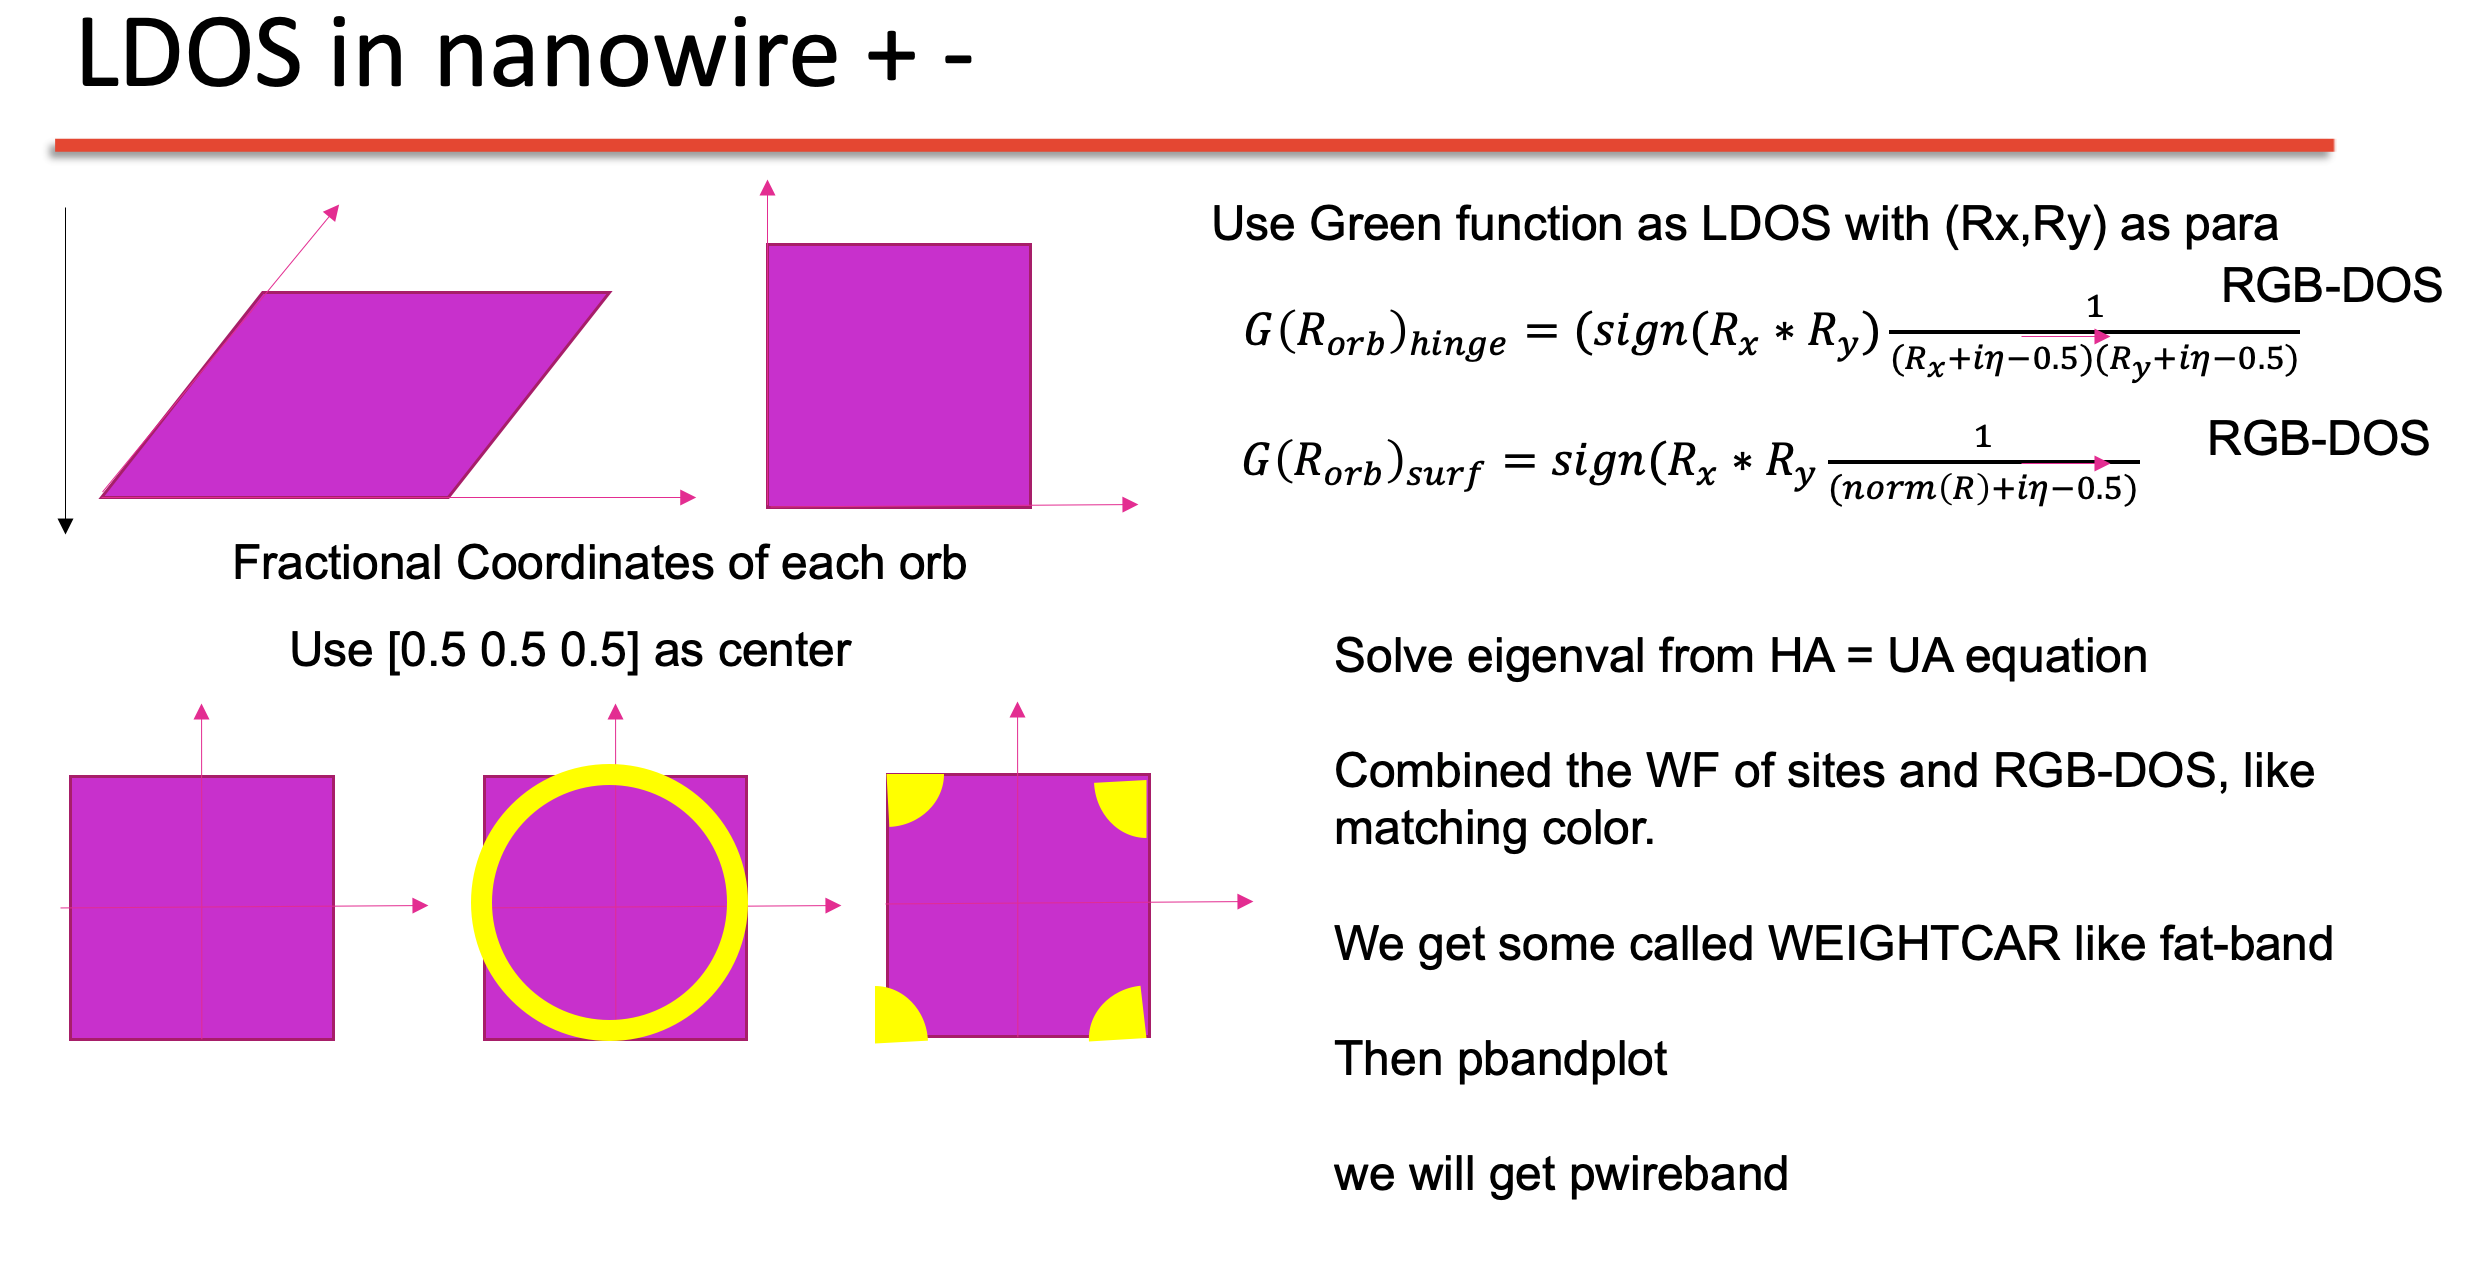

### Corner

bugs here

calculate =4;
M =1;
m_0 = 0;
theta_0 = 0*pi;
RCI_d = RCI;
RCI_d = RCI_d.descritize([20 20 0])

Setting 5/5Htrig ...


RCI_d =   Htrig - 属性:

          Kinds: 3
          HcoeL: [4×4×3 sym]
          HnumL: [4×4×3 double]
     HsymL_trig: [Sigma_x_N__N*Sigma_y_N__N    Sigma_x_1__N*Sigma_y_N__N    Sigma_y_1__N*Sigma_x_N__N]
      Htrig_sym: [4×4 sym]
      Basis_num: 4
             Rm: [3×3 double]
             Gk: [3×3 double]
    symvar_list: M

\left(\begin{array}{cccc} M\,\Sigma _{x,N}^{N}\,\Sigma _{y,N}^{N}-\frac{\Sigma _{y,1}^{N}\,\Sigma _{x,N}^{N}}{2}-\frac{\Sigma _{x,1}^{N}\,\Sigma _{y,N}^{N}}{2} & \frac{\Sigma _{x,1}^{N}\,\Sigma _{y,N}^{N}\,1{}\mathrm{i}}{2} & 0 & -\frac{\Sigma _{y,1}^{N}\,\Sigma _{x,N}^{N}\,1{}\mathrm{i}}{2}\\ \frac{\Sigma _{x,1}^{N}\,\Sigma _{y,N}^{N}\,1{}\mathrm{i}}{2} & -M\,\Sigma _{x,N}^{N}\,\Sigma _{y,N}^{N}+\frac{\Sigma _{y,1}^{N}\,\Sigma _{x,N}^{N}}{2}+\frac{\Sigma _{x,1}^{N}\,\Sigma _{y,N}^{N}}{2} & \frac{\Sigma _{y,1}^{N}\,\Sigma _{x,N}^{N}\,1{}\mathrm{i}}{2} & 0\\ 0 & \frac{\Sigma _{y,1}^{N}\,\Sigma _{x,N}

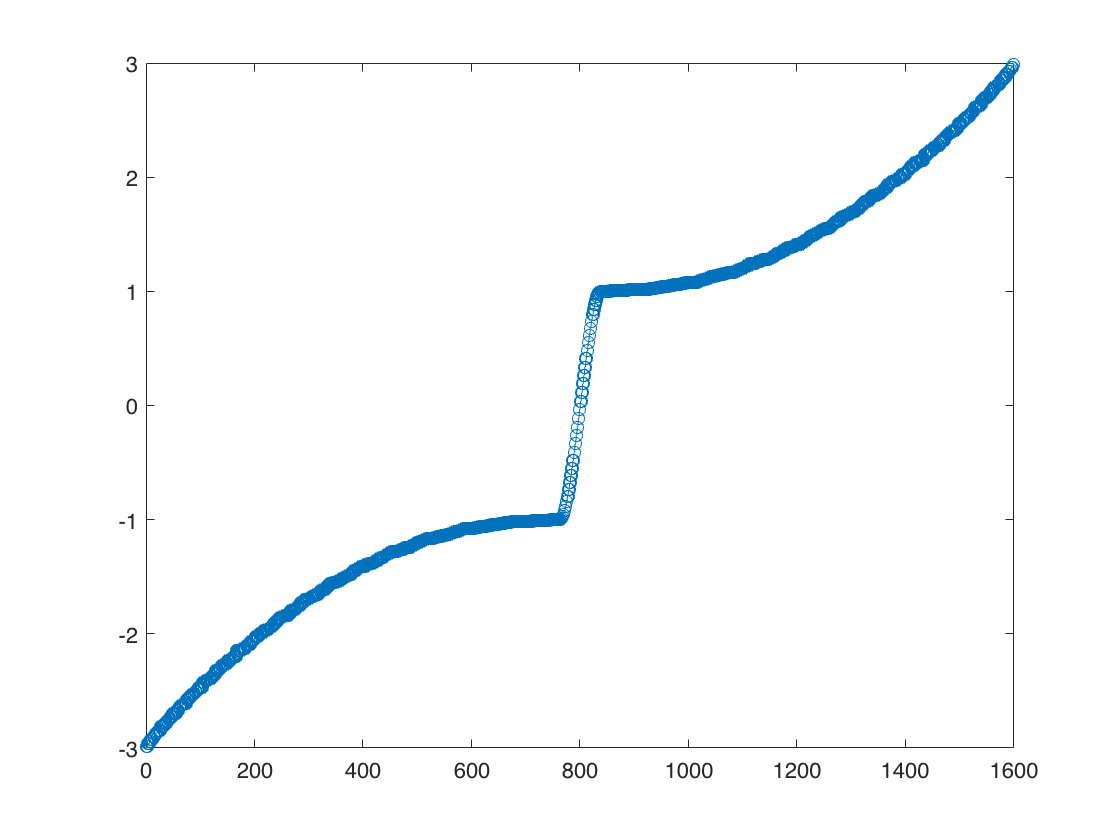

RCI_d = RCI_d <'KPOINTS_wire';M = 1;
RCI_d = RCI_d.Subsall();
[EIGENCAR_disk,...
WAVECAR_disk] = RCI_d.EIGENCAR_gen_wire('klist',[0,0,0]);
figure();
plot(EIGENCAR_disk,'-o')

glance mode
        1600



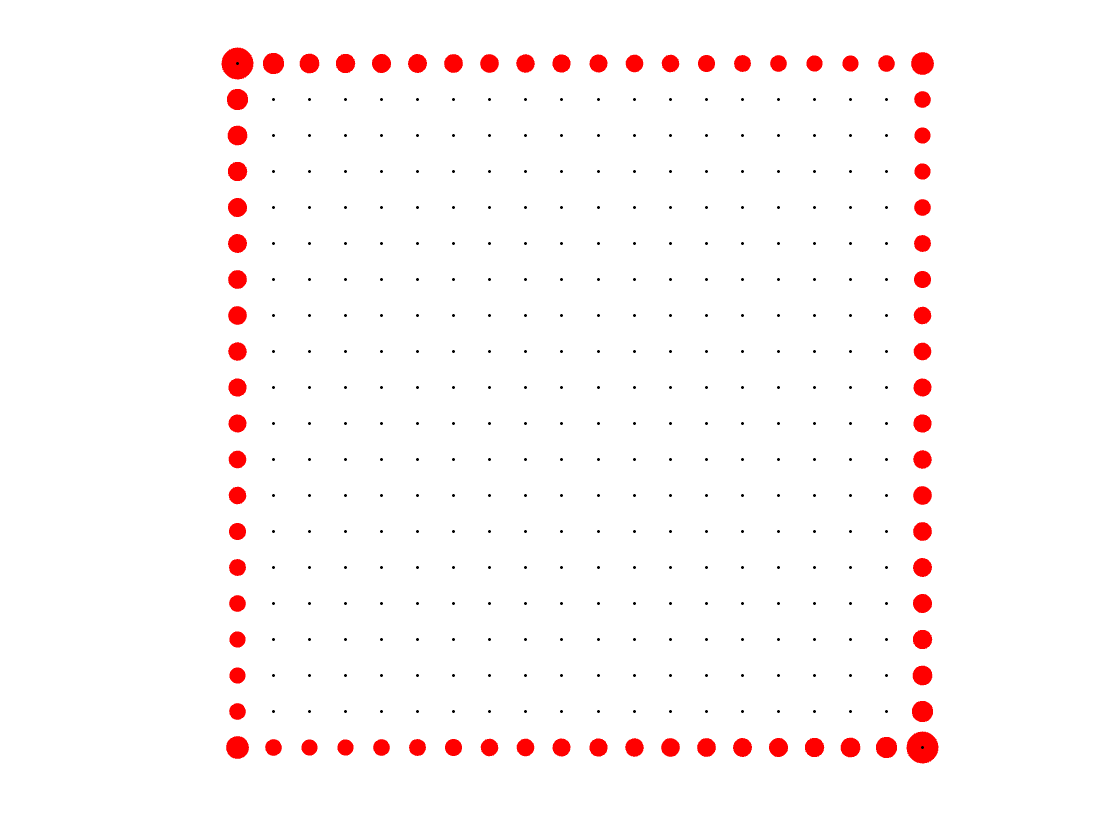

ans =          0         0         0    0.1268
         0         0         0    0.1238
         0         0         0    0.1268
         0         0         0    0.1298
    0.0500         0         0    0.0683
    0.0500         0         0    0.0568
    0.0500         0         0    0.0552
    0.0500         0         0    0.0666
    0.1000         0         0    0.0649
    0.1000         0         0    0.0481


figure();
PARCHG_gen(RCI_d.orbL,WAVECAR_disk(:,800:801)*3)

syms theta_x theta_y real;
if calculate ==5
RCI_d.HcoeL = subs(RCI_d.HcoeL);
RCI_d = RCI_d.Subsall('para',[sym('theta_x'),sym('theta_y')]);
[EIGENCAR_disk,WAVECAR_disk,WEIGHTCAR_disk]= RCI_d.EIGENCAR_gen_wire('klist',[0,0,0],'norb',-1,'paraname',[sym('theta_x'),sym('theta_y')],'para',pi*[(0:0.02:2).',(0:0.02:2).']);
% [klist_l,kpoints_l,kpoints_name] = RCI_d.kpath_information();
pbandplot((WEIGHTCAR_disk),EIGENCAR_disk,[-0.5,0.5],'RCI-disk \theta_x = \theta_y =0:2\pi ',@turbo,(0:0.02:2),[0,0.5,1.0,1.5,2],["0","\pi/2","\pi","3\pi/4","2\pi"]);
%pbandplot(sign(WEIGHTCAR_disk),EIGENCAR_disk,[-1,1],'RCI-disk \theta_x = \theta_y =0:1 ',@turbo,0:0.01:1,[0,1/3,1],['0','\pi/3','\pi']);
%bandplot(EIGENCAR_disk,[-1,1],'RCI-slab \theta_x = - \theta_y =0:1 ',@turbo,0:0.01:1,[0,1/3,1],['0','\pi/3','\pi']);
end


### TEST FOR PERTUBATION FORM